# Optimal Estimation - Homework 2

### Tanner Koza

## Problem 1

Two random variables $x_1$ and $x_2$ have a joint PDF that is uniform inside the circle (in the $x_1$-$x_2$ plane) with radius 2, and zero outside the circle.

### Find: 

- **Part A: **Find the math expression of the joint PDF function.

- **Part B: **Find the conditional PDF $P_{x_1|x_2}(x_2|x_1=0.5)$.

- **Part C: **Are the two random variables uncorrelated?

- **Part D: **Are the two random variables statistically independent? Hint: find $p_{x_1}(x_1)$ and $p_{x_2}(x_2)$ and check if $p_{x_1x_2}(x_1,x_2)=p_{x_1}(x_1)p_{x_2}(x_2)$.

### Solution: 

- **Part A: **Considering the joint PDF of these two random variables is uniform inside of a circle, the probabilities of the PDF are represented by the height of a cylinder created by the circle. The volume of this circle should sum to 1, therefore, the height (probability) within the bounds of the circle is $h = \frac{1}{\pi r^2}$, where $r$ is 2. This probabilty makes up half of the piecewise that defines the whole joint PDF below:


$$f_{x_1x_2}(x_1,x_2) = \left\{
        \begin{array}{ll}
            \frac{1}{4\pi} & \quad \sqrt{x_1^2 + x_2^2}  \le 2 \\
            0 & \quad else 

        \end{array}
    \right.$$


- **Part B: **The conditional PDF can be found using the following:


$$P_{x_1|x_2}(x_2|x_1=0.5) = \frac{f_{x_1x_2}}{f_{x_1}}$$


$f_{x_1x_2}$ is defined within the circle in Part A and $f_{x_1}$ is defined as follows:


$$f_{x_1}=\int f_{x_1x_2}(x_1,x_2)dx_2$$


where the bounds across $x_2$ are given by the condition of $x_1 = 0.5$ below:


$$\sqrt{(0.5)^2+x_2^2}\le2
$$



$$0.25+x_2^2\le4$$



$$x_2^2\le3.75$$



$$x_2 = \pm \sqrt{3.75$$


Using these bounds, $f_{x_1}$ is:


$$f_{x_1} = \int_{-\sqrt{3.75}}^{\sqrt{3.75}}\frac{1}{4\pi}dx_2$$



$$\left. = \frac{x_2}{4 \pi} \right|^{\sqrt{3.75}}_{-\sqrt{3.75}$$



$$\left. = \frac{2\sqrt{3.75}}{4\pi}$$


Finally, evaluating the conditional probability yields:


$$P_{x_1|x_2}(x_2|x_1=0.5) = \frac{1}{4\pi}(\frac{4\pi}{2\sqrt{3.75}})=\frac{1}{2\sqrt{3.75}}$$


- **Part C: **The two random variables are uncorrelated and can be proven with the following uncorrelated property:


$$E[x_1x_2]-E[x_1]E[x_2] =0
$$


where $E[x_1]$ and $E[x_2]$ are $0$ as all possible values for each are uniformly centered around $0$. This was assumed based on the prompt stating the joint PDF is a circle. $E[x_1x_2]$ is evaluated as the following:


$$E[x_1x_2] = \int \int x_1x_2 f_{x_1x_2}(x_1,x_2)dx_1dx_2$$



$$= \int \int x_1 x_2 (\frac{1}{4\pi})dx_1dx_2$$


where the bounds across each random variable are given by the following:


$$\pm\sqrt{4-x_1^2}$$



$$\pm\sqrt{4-x_2^2}$$


Therefore, $E[x_1x_2]$ is:


$$E[x_1x_2] = \frac{1}{4\pi}\int_{-\sqrt{4-x_1^2}}^{\sqrt{4-x_1^2}} x_2 \left. (\frac{x_1^2}{2}) \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}} = 0$$


Because of the following:


$$\left. (\frac{x_1^2}{2}) \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}} = 0$$


Therefore:


$$E[x_1x_2]-E[x_1]E[x_2] =0 - (0)(0) = 0$$


meaning the two random variables are uncorrelated.

- **Part D: **The two random variables are statistically dependent and can be proven with the following independence property:


$$f_{x_1x_2} = f_{x_1}f_{x_2}$$


The PDFs for $x_1$ and $x_2$ can be found using the same method in Part B with the general bounds used in Part C. $f_{x_1}$ is the following:


$$f_{x_1} = \int_{-\sqrt{4-x_1^2}}^{\sqrt{4-x_1^2}}\frac{1}{4\pi}dx_2$$



$$\left. = \frac{x_2}{4 \pi} \right|^{\sqrt{4-x_1^2}}_{-\sqrt{4-x_1^2}$$



$$\left. = \frac{2\sqrt{4-x_1^2}}{4\pi}$$


$f_{x_2}$ is the following:


$$f_{x_2} = \int_{-\sqrt{4-x_2^2}}^{\sqrt{4-x_2^2}}\frac{1}{4\pi}dx_1$$



$$\left. = \frac{x_1}{4 \pi} \right|^{\sqrt{4-x_2^2}}_{-\sqrt{4-x_2^2}$$



$$\left. = \frac{2\sqrt{4-x_2^2}}{4\pi}$$


Evaluating the independence property, it can be seen the joint PDF and multiplied PDF are not equal. Therefore, $x_1$ and $x_2$ are statistically dependent.


$$\frac{1}{4\pi} \neq (\frac{2\sqrt{4-x_1^2}}{4\pi})(\frac{2\sqrt{4-x_2^2}}{4\pi})$$


## Problem 2

The stationary process $x(t)$ has an autocorrelation function of the form:


$$R_x(\tau) = \sigma^2e^{-\beta |\tau|}$$


Another process $y(t)$ is related to $x(t)$ by the deterministic equation:


$$y(t) = ax(t) + b$$


where the constants $a$ and $b$ are known.

### **Find:**

- **Part A: **What is the autocorrelation function for $y(t)$?

- **Part B: **What is the crosscorrelation function $R_{xy}(\tau) = E[x(t)y(t+\tau)]$?

### Solution:

- **Part A: ** The following is the solution for the autocorrelation of $y(t)$:


$$R_y(t_1, t_2) = E[y(t_1)y(t_2)]$$



$$= E[(ax(t_1)+b)(ax(t_2)+b)]$$



$$= E[a^2x(t_1)x(t_2) + abx(t_1) + abx(t_2) + b^2]$$



$$= a^2E[x(t_1)x(t_2)] + abE[x(t_1)] + abE[x(t_2)] + b^2$$


Considering:


$$E[x(t_1)] = E[x(t_2)] = \bar{x}$$


and


$$E[x(t_1)x(t_2)] = \sigma^2e^{-\beta |\tau|}$$



$$R_y(t_1,t_2) = a^2\sigma^2e^{-\beta |\tau|} + 2ab\bar{x}+ b^2$$


This can be reduced further given the property $R(\tau = 0) = \sigma^2 +  \bar{x^} ^2$. Knowing $R_x(0) = \sigma^2 e^{-\beta|0|} = \sigma^2$, then $\bar{x}$ is known to be 0. This means the autocorrelation of $y(t)$ is:


$$R_y(t_1,t_2) = a^2\sigma^2e^{-\beta |\tau|}+ b^2$$


- **Part B: **The following is the solution for the crosscorrelation function for $x(t)$ and $y(t)$:


$$R_{xy}(\tau) = E[x(t)y(t+\tau)] = E[x(t_1)(ax(t_2)+b)]$$



$$= E[ax(t_1)x(t_2) + bx(t_1)]$$



$$=aE[x(t_1)x(t_2)] + bE[x(t_1)]$$



$$= a\sigma^2e^{-\beta |\tau|} + b\bar{x}$$



$$= a\sigma^2e^{-\beta |\tau|}$$


## Problem 3

Use least squares to identify a gyroscopes scale factor $(a)$ and bias $(b)$. Simulate the gyroscope using:


$$g(k) = ar(k) + b + n(k)$$



$$n\tilde{}N(0,\sigma = 0.3 degs/s)$$



$$r(k) = 100sin(\omega t)$$


### Find:

- **Part A: **Perform the least squares with 10 samples.

- **Part B: **Repeat Part A 1000 times and calculates the mean and standard deviation of the estimate errors. Compare the results to the theoretically expected mean and standard deviation.

- **Part C: **Repeat Parts A & B using 1000 samples. What does the theoretical and Monte-Carlo standard deviation of the estimated errors approach?

- **Part D: **Set up the problem to run as a recursive least squares and plot the coefficients and theoretical standard deviation of the estimate error and the actual estimate error as a function of time.

### Solution:

- **Part A & B: ** A scale factor of 3 and a bias of 10 were selected for $a$ and $b$ to be estimated. The following code shows the batched least squares estimation with 10 samples. The first estimate of $a$ was 2.999 and the first estimate of $b$ was 9.966. The resulting plots show the estimated mean and standard deviation plotted along with each Monte Carlo simulation's estimate for both the scale factor and bias. The scale factor estimated mean was 3 which is exactly what the theoretical mean is. The bias estimated mean was 10.0027 which is really close to the theoretical mean of 10. The scale factor estimated standard deviation was 0.0014 while the theoretical standard deviation extracted from the covariance matrix was 0.0013. The bias estimated standard deviation was 0.0926 while the theoretical standard deviation extracted from the covariance matrix was 0.0949. These values aren't as close as the scale factor values, but still accurately depict the statistics in a simulation environment.

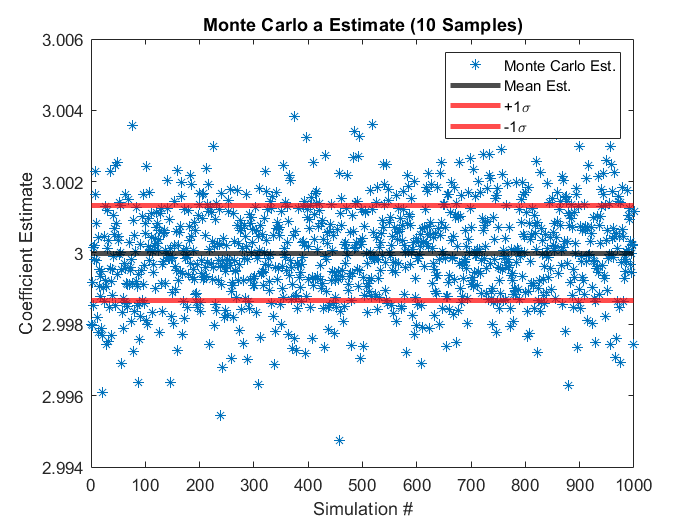

%% Parts A & B

% Time Initialization
dt = 0.1;
t_end = 30;
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Least Squares Initialization
estSamps = 10; % # of samples used in estimate
R = var * eye(estSamps);

% Preallocation
r = zeros(numSamps,1); 
g = zeros(numSamps,1);
est = zeros(numSims,2);


for i = 1:numSims

    n = sigma * randn(numSamps,1);

    for k = 1:numSamps
       
        r(k) = 100 * sin(omega * t(k));
    
        g(k) = a * r(k) + b + n(k); % degs/s
    
    end

H = [r(1:estSamps) ones(estSamps,1)];
est(i,:) = (H' * H)^-1 * H' * g(1:estSamps);

P = (H' * R^-1 * H)^-1 ;
end

mean_est = mean(est);
std_est = std(est); % Monte Carlo Standard Deviation

std_a = sqrt(P(1,1)); % Theoretical Standard Deviation
std_b = sqrt(P(2,2));

figure
plot(1:numSims, est(:,1), '*')
hold on
yline(mean_est(1),'k','LineWidth',3)
yline(mean_est(1) + std_est(1),'r','LineWidth',3)
yline(mean_est(1) - std_est(1),'r','LineWidth',3)
title('Monte Carlo a Estimate (10 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')
legend('Monte Carlo Est.','Mean Est.','+1\sigma','-1\sigma')

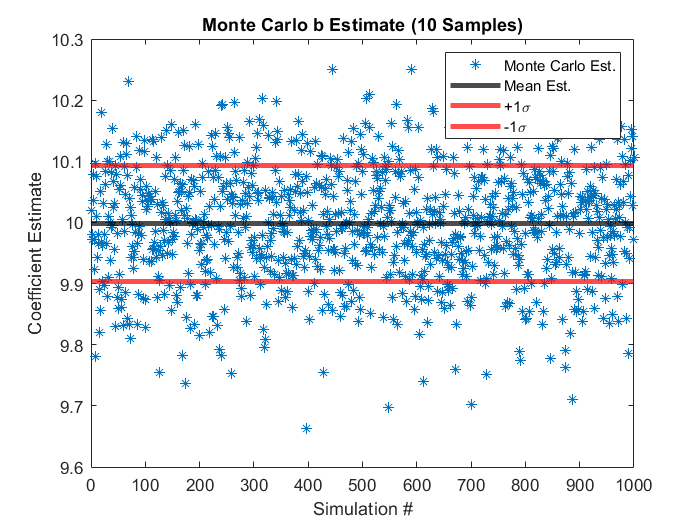


figure
plot(1:numSims, est(:,2), '*')
hold on
yline(mean_est(2),'k','LineWidth',3)
yline(mean_est(2) + std_est(2),'r','LineWidth',3)
yline(mean_est(2) - std_est(2),'r','LineWidth',3)
title('Monte Carlo b Estimate (10 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')
legend('Monte Carlo Est.','Mean Est.','+1\sigma','-1\sigma')


clearvars



- **Part C: **The following code shows the batched least squares estimation with 1000 samples. The first estimate of $a$ was 2.999 and the first estimate of $b$ was 10.010. The resulting plots show the estimated mean and standard deviation plotted along with each Monte Carlo simulation's estimate for both the scale factor and bias. The scale factor estimated mean was 3 which is exactly what the theoretical mean is. The bias estimated mean was 10.0001 which is more or less exactly the theoretical mean of 10. The scale factor estimated standard deviation was 0.0001345 while the theoretical standard deviation extracted from the covariance matrix was 0.0001345. The two are the same. The bias estimated standard deviation was 0.0095 while the theoretical standard deviation extracted from the covariance matrix was 0.0095. The two are also the same. This shows how using a larger batch of samples in a least squares estimation accurately recreates the theoretical statistics when in a simulation environment. The errors of the theoretical and estimated statistics approach 0.

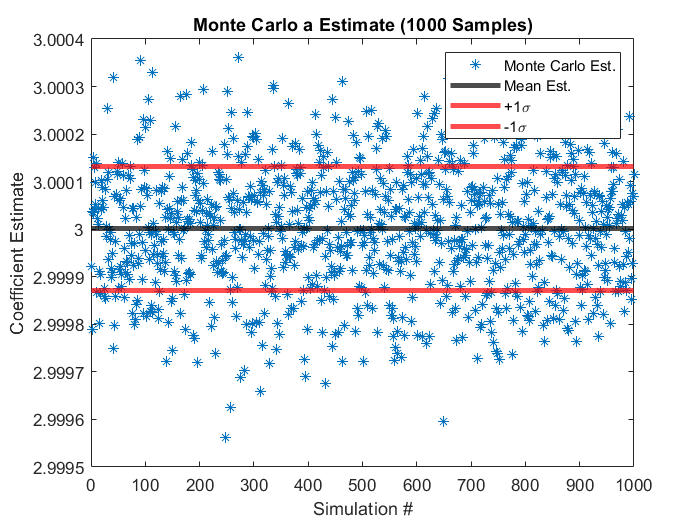

%% Part C

% Time Initialization
dt = 0.1;
t_end = 300;
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Least Squares Initialization
estSamps = 1000; % # of samples used in estimate
R = var * eye(estSamps);

% Preallocation
r = zeros(numSamps,1); 
g = zeros(numSamps,1);
est = zeros(numSims,2);


for i = 1:numSims

    n = sigma * randn(numSamps,1);

    for k = 1:numSamps
       
        r(k) = 100 * sin(omega * t(k));
    
        g(k) = a * r(k) + b + n(k); % degs/s
    
    end

H = [r(1:estSamps) ones(estSamps,1)];
est(i,:) = (H' * H)^-1 * H' * g(1:estSamps);

P = (H' * R^-1 * H)^-1 ;
end

mean_est = mean(est);
std_est = std(est); % Monte Carlo Standard Deviation

std_a = sqrt(P(1,1)); % Theoretical Standard Deviation
std_b = sqrt(P(2,2));

figure
plot(1:numSims, est(:,1), '*')
hold on
yline(mean_est(1),'k','LineWidth',3)
yline(mean_est(1) + std_est(1),'r','LineWidth',3)
yline(mean_est(1) - std_est(1),'r','LineWidth',3)
title('Monte Carlo a Estimate (1000 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')
legend('Monte Carlo Est.','Mean Est.','+1\sigma','-1\sigma')

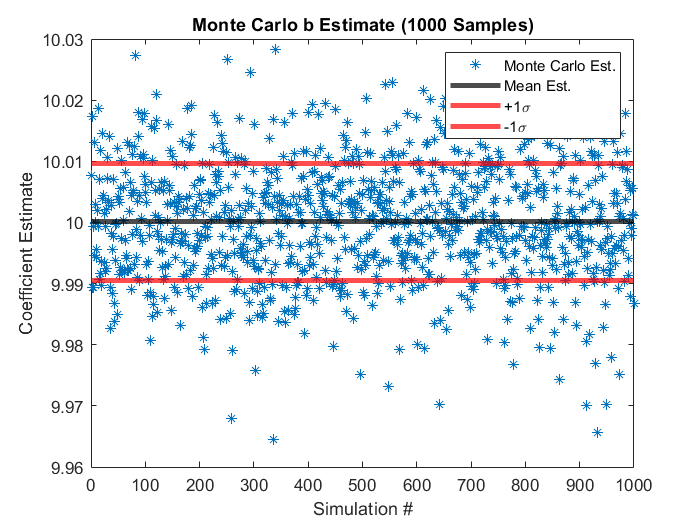


figure
plot(1:numSims, est(:,2), '*')
hold on
yline(mean_est(2),'k','LineWidth',3)
yline(mean_est(2) + std_est(2),'r','LineWidth',3)
yline(mean_est(2) - std_est(2),'r','LineWidth',3)
title('Monte Carlo b Estimate (1000 Samples)')
xlabel('Simulation #')
ylabel('Coefficient Estimate')
legend('Monte Carlo Est.','Mean Est.','+1\sigma','-1\sigma')


clearvars

- **Part D: **The following plots show the scale factor and bias estimates over time using Recursive Least Squares, the theoretical standard deviations, and the residuals of the estimates. It can be seen that the estimates are spot on over time without noticeable deviation (except at beginning as noted by residual plot). The theoretical standard deviation plot shows certainty of the estimates stays the same except for the brief period at the beginning where they are transient after leaving their initialized values. The actual error (residual plot) shows the errors stay within the theoretical standard deviation but are a little larger at the beginning as the estimate converges over time although this is tough to see in the estimate plot.

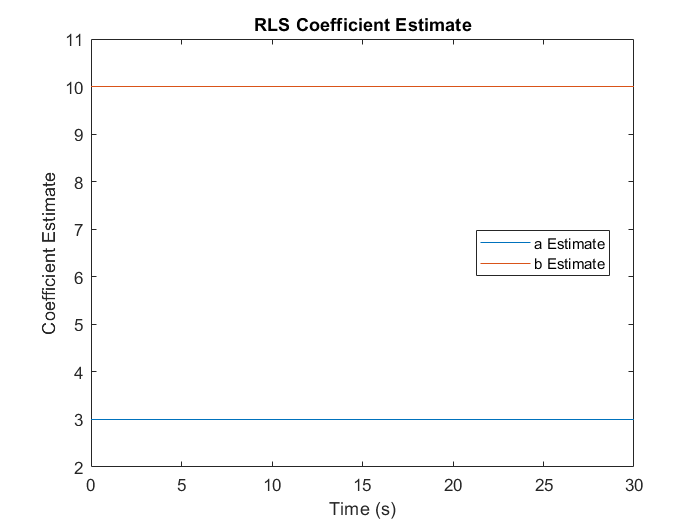

%% Part D

% Time Initialization
dt = 0.1;
t_end = 30; % s
t = 0:dt:t_end;
numSamps = length(t);

% Monte Carlo Initialization
numSims = 1000;

% Noise & Frequency Initialization
sigma = 0.3; % deg/s
var = sigma^2;
freq = 2;
omega = freq * (2 * pi) ; % rads/s

% Arbitrary Coefficient Initialization
a = 3;
b = 10;

% Recursive Least Squares Initialization
est = zeros(2,1);
R = var;
P = eye(2);

% Preallocation
est_a = zeros(numSamps,numSims);
est_b = zeros(numSamps,numSims);
std_a = zeros(numSamps,numSims);
std_b = zeros(numSamps,numSims);


for i = 1:numSims

    n = sigma * randn(numSamps,1);
    r = 100 * sin(omega .* t);
    g = a * r' + b + n;

    for j = 1:numSamps

        H = [r(j) 1];

        K = P * H' * (H * P * H' + R)^ -1;

        est =  est + K * (g(j) - H * est);

        est_a(j,i) = est(1);
        est_b(j,i) = est(2);

        P = (P^-1 + H' * R^-1 * H)^ -1;

        std_a(j,i) = sqrt(P(1,1));
        std_b(j,i) = sqrt(P(2,2)); 

    end

end

mean_est_a = mean(est_a,2);
mean_est_b = mean(est_b,2);

th_std_a = mean(std_a,2);
th_std_b = mean(std_b,2);

mc_std_a = std(est_a,0,2);
mc_std_b = std(est_b,0,2);

figure
plot(t,mean_est_a)
hold on
plot(t,mean_est_b)
title('RLS Coefficient Estimate')
xlabel('Time (s)')
ylabel('Coefficient Estimate')
legend('a Estimate','b Estimate','Location',"best")
ylim([2 11])

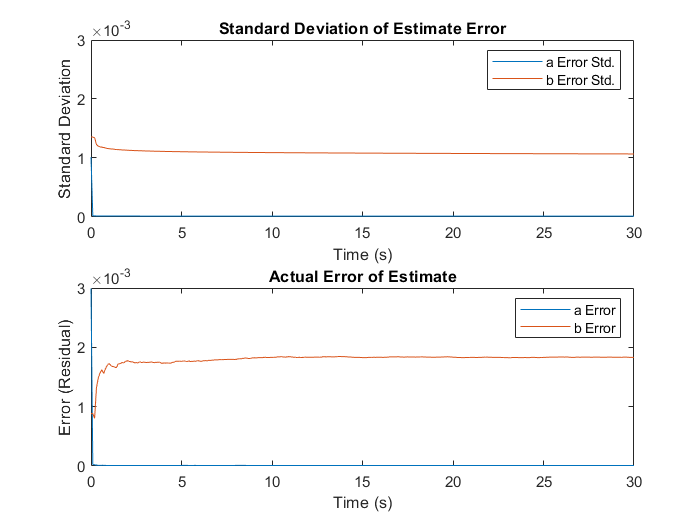


figure
ax(1) = subplot(2,1,1);
plot(t,th_std_a, 'Parent', ax(1))
hold on
plot(t,th_std_b, 'Parent', ax(1))
title('Standard Deviation of Estimate Error')
xlabel('Time (s)')
ylabel('Standard Deviation')
legend('a Error Std.','b Error Std.')

ax(2) = subplot(2,1,2);
plot(t,abs(a - mean_est_a),'Parent', ax(2))
hold on
plot(t,abs(b - mean_est_b), 'Parent', ax(2))
title('Actual Error of Estimate')
xlabel('Time (s)')
ylabel('Error (Residual)')
legend('a Error','b Error')

linkaxes(ax,'y');

## **Problem 4**

Least Squares for System I.D.  Simulate the following discrete system with a normal random input and output noise:


$$G(z)= \frac{0.25(z-0.8)}{z^2-1.90z+0.95}$$


### Find: 

- **Part A: **Develop the H matrix for the least squares solution.

- **Part B: **Use least squares to estimate the coefficients of the above Transfer Function. How good is the fit?  Plot the bode response of the I.D. TF and the simulated TF on the same plot.  How much relative noise has been added (SNR – signal to noise ratio), plot y and Y on the same plot.

- **Part C: **Repeat the estimation process about 10 times using new values for the noise vector each time.  Compute the mean and standard deviation of your parameter estimates. Compare the computed values of the parameter statistics with those predicted by the theory based on the known value of the noise statistics.

- **Part D: **Now use sigma between 0.1 and 1.0 and repeat parts b and c.

- **Part E: **What can you conclude about using least squares for sys id with large amounts of noise?

### Solution: 

- **Part A: **one row of the H matrix was solved for with the following and used for the 1000 samples in a batched implementation of Least Squares:


$$G(z)= \frac{Az-B}{z^2-Cz+D}=\frac{y}{u}$$


The discrete transfer function was generalized into the above transfer function to be able to solve for coefficients.


$$yz^2-yCz+yD=uAz-uB$$



$$y_{k+1} = Au_{k} - Bu_{k-1} + Cy_{k} - Dy_{k-1}$$



$$H_{row} = \left[\matrix{u_k & -u_{k-1} & y_k & -y_{k-1}} \right]$$


- **Part B: ** The following code depicts an implementation of a large batched least squares estimation of the system coefficients. The fit is really good as the coefficient estimates provide the following estimated transfer function:


$$G(z)= \frac{0.2503(z-0.7934)}{z^2-1.8942z+0.9444}$$


or


$$G(z)= \frac{0.2503z-0.1986}{z^2-1.8942z+0.9444}$$


The Bode plots for both of the transfer functions also look very similar with only slight deviation. The SNR for this case was 109.46 meaning an accurate estimate can be achieved as the estimate doesn't fit to as much noise. The plot of the clean output and noisy output are also shown and have essentially no noticeable difference.

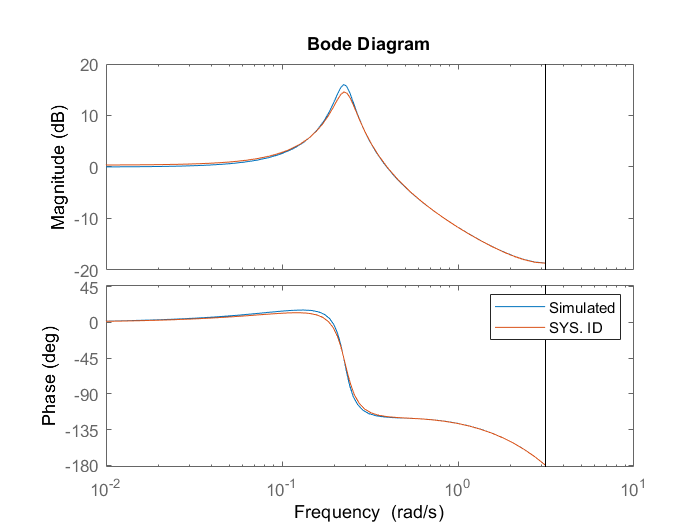

%% Part A & B

numd = 0.25 * [1 -0.8];
dend = [1 -1.9 0.95];

dt = 1/100;

TF = tf(numd,dend,1);

u = randn(1000,1);
numSamps = length(u);

y = dlsim(numd, dend, u);

sigma = 0.01;
noise = sigma * randn(1000,1);
Y = y + noise;

H = [u(2:end-1) -u(1:end-2) Y(2:end-1) -Y(1:end-2)];

est = (H' * H)^-1 * H' * Y(3:end);

TFS = tf([est(1) -est(2)], [1 -est(3) est(4)],1);

figure
bode(TF)
hold on
bode(TFS)
legend('Simulated','SYS. ID')

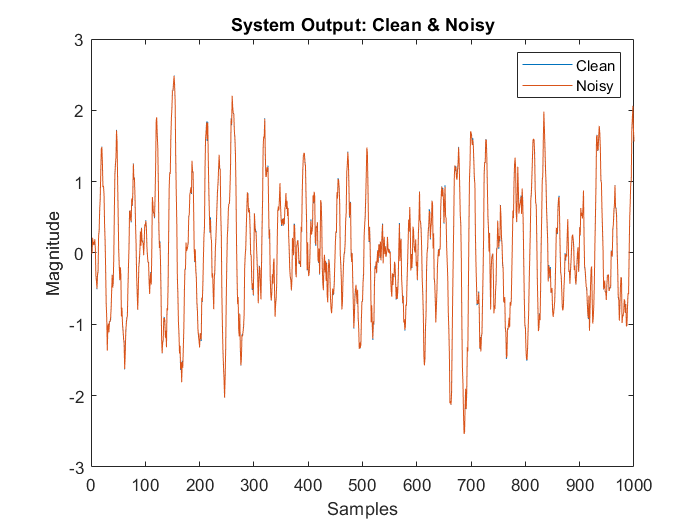


% SNR 
snr = std(Y)/sigma;

figure
plot(y)
hold on
plot(Y)
title('System Output: Clean & Noisy')
xlabel('Samples')
ylabel('Magnitude')
legend('Clean','Noisy')

- **Part C: **Part B was repeated 10 times and produced the following values for the Monte Carlo mean and standard deviations of coefficients A-D:


$$\bar{A} = 0.2501$$



$$\bar{B} = 0.1983$$



$$\bar{C} = 1.8920$$



$$\bar{D} = 0.9423$$



$$\sigma_A = 5e-4$$



$$\sigma_B = 0.001$$



$$\sigma_C = 0.0021$$



$$\sigma_D = 0.0021$$


The Monte Carlo statistics prove to be fairly similar for the mean but different for the standard deviation of the theoretical statistics. This is because the estimates are good, but the small number of simulations doesn't quite capture the variance statistics very well. The theoretical mean and standard deviation values are:


$$\bar{A} = 0.25$$



$$\bar{B} = 0.2$$



$$\bar{C} = 1.9$$



$$\bar{D} = 0.95$$



$$\sigma_A = 9e-6$$



$$\sigma_B = 2e-5$$



$$\sigma_C = 3e-4$$



$$\sigma_D =3e-4$$


- **Part D: **Parts B & C were repeated for a $\sigma_{noise}$ of 0.5. The fit is really poor as the coefficient estimates provide the following estimated transfer function:


$$G(z)= \frac{0.2457(z+0.6146}{z^2-0.5639z+-0.2628}$$


or


$$G(z)= \frac{0.2457z+0.151}{z^2-0.5639z+-0.2628}$$


The Bode plots for both of the transfer functions also look very different. The SNR for this case was 2.62 meaning an inaccurate estimate isachieved as the estimate is esstentially only fitting to noise. The plot of the clean output and noisy output are also shown and have a greater difference than in Part B as the variance of the noise added increased.

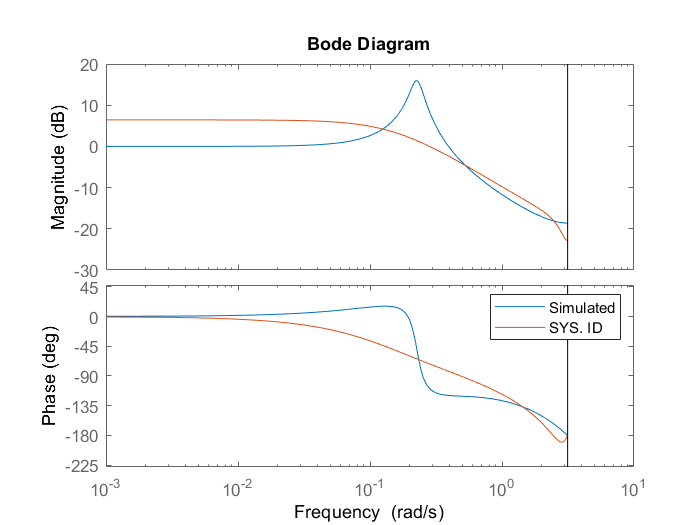

numd = 0.25 * [1 -0.8];
dend = [1 -1.9 0.95];

dt = 1/100;

TF = tf(numd,dend,1);

u = randn(1000,1);
numSamps = length(u);

y = dlsim(numd, dend, u);

sigma = 0.5;
noise = sigma * randn(1000,1);
Y = y + noise;

H = [u(2:end-1) -u(1:end-2) Y(2:end-1) -Y(1:end-2)];

est = (H' * H)^-1 * H' * Y(3:end);

TFS = tf([est(1) -est(2)], [1 -est(3) est(4)],1);

figure
bode(TF)
hold on
bode(TFS)
legend('Simulated','SYS. ID')

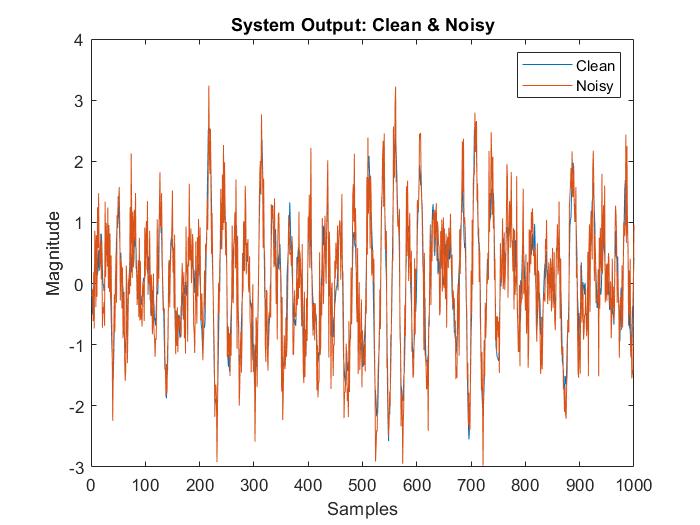


% SNR 
snr = std(Y)/sigma;

figure
plot(y)
hold on
plot(Y)
title('System Output: Clean & Noisy')
xlabel('Samples')
ylabel('Magnitude')
legend('Clean','Noisy')


numSims = 10;
est = zeros(4,numSims);

for i = 1:numSims

    u = randn(1000,1);
    numSamps = length(u);

    y = dlsim(numd, dend, u);

    sigma = 0.5;
    noise = sigma * randn(1000,1);
    Y = y + noise;

    H = [u(2:end-1) -u(1:end-2) Y(2:end-1) -Y(1:end-2)];

    est(:,i) = (H' * H)^-1 * H' * Y(3:end);

end

P = sigma * (H' * H)^-1;

mean_est = mean(est,2);
std_est = std(est,0,2);

The estimation was repeated 10 times and produced the following values for the Monte Carlo mean and standard deviations of coefficients A-D:


$$\bar{A} = 0.2513$$



$$\bar{B} = -0.1334$$



$$\bar{C} = 0.4857$$



$$\bar{D} = -0.3196$$



$$\sigma_A = 0.0238$$



$$\sigma_B = 0.0169$$



$$\sigma_C = 0.0195$$



$$\sigma_D = 0.0204$$


The Monte Carlo statistics prove to be extremely for the mean and standard deviation of the theoretical statistics. This is because the estimates are fitting to noise and the small number of simulations doesn't quite capture the statistics very well. The theoretical mean and standard deviation values are:


$$\bar{A} = 0.25$$



$$\bar{B} = 0.2$$



$$\bar{C} = 1.9$$



$$\bar{D} = 0.95$$



$$\sigma_A = 5e-4$$



$$\sigma_B = 6e-4$$



$$\sigma_C = 0.0010$$



$$\sigma_D =9.7e-4$$


- **Part E: **Given the results of Part D, least squares system identification with large noise is not plausible as the estimates are heavily corrupted by the noise. The estimator essentially fits the noise which ignores the dynamics of the whatever system you are trying to estimate.

## Problem 5

Justification of white noise for certain problems. Consider two problems:

 (i) Simple first order low-pass filter with bandlimited white noise as the input:

$y = G(s)\omega$, so that $S_y(j\omega)=|G(j\omega)|^2S_\omega(j\omega)$ and the noise has PSD


$$S_1(\omega) = \left\{
        \begin{array}{ll}
            A& \quad |\omega|\le\omega_c \\
            0 & \quad |\omega|>\omega_c 

        \end{array}
    \right.$$



$$G(s)= \frac{1}{T_\omega s+1$$


(ii) The same low pass system, but with pure white noise as the input.


$$S_2(\omega)=A, \forall \omega$$



$$G(s)= \frac{1}{T_\omega s+1$$


The first case seems quite plausible, but the second case has an input with infinite variance and so is not physically realizable.  However, the white noise assumption simplifies the system analysis significantly, so it is important to see if the assumption is justified.  We test this with our two examples above.

### Find:

- **Part A: **Sketch the noise PSD and $|G(j\omega)|$ for a reasonable $T_\omega$ and $\omega_c$ for each case.

- **Part B: **Determine $S_y(j\omega)$ for the two cases. Sketch these too.

- **Part C: **Determine $E[y^2]$ for the two cases.

- **Part D: **Use these results to justify the following statement:

If the input spectrum is flat considerably beyond the system bandwidth, there is little error introduced by assuming that the input spectrum is flat out to infinity. 

### Solution:

- **Part A:**

- **Part B: **Considering $S_y(j\omega)=|G(j\omega)|^2S_\omega(j\omega)$, $|G(j\omega)|^2$ is the following:


$$|G(j\omega)|^2 = \left |\frac{1}{T_\omega (j\omega)+1} \right |^2$$



$$= \frac{1}{T_\omega^2 (\omega^2)+1}$$


Using $S_1(\omega)$and $S_2(\omega)$ defined above, $S_y(j\omega)$ for the first case is:


$$S_y(j\omega) = \left\{
        \begin{array}{ll}
            \frac{A}{T_\omega^2 (\omega^2)+1}& \quad |\omega|\le\omega_c \\
            0 & \quad |\omega|>\omega_c 

        \end{array}
    \right.$$


And $S_y(j\omega)$ for the second case is:


$$S_y(j\omega) = \frac{A}{T_\omega^2 (\omega^2)+1}$$


The sketches of these are as follows:

- **Part C: **$E[y^2]$ for the first case is derived as so:

Understanding $E[y^2]$ is the variance of $y$ given the white noise is zero mean, the following can be said 


$$E[y^2] = R(0)= \int_{-\infty}^{\infty}S_y(j\omega)d\omega$$


Therefore, for the first case


$$E[y^2] =
        
            \int_{-\omega_c}^{\omega_c}\frac{A}{T_\omega^2 (\omega^2)+1}d\omega    $$


The integral can be evaluated as so,


$$E[y^2] =\frac{A}{T_\omega^2}\int_{-\omega_c}^{\omega_c}\frac{1}{\omega^2+\frac{1}{T_\omega^2}
$$


Using the common integral $\int \frac{1}{a^2 +u^2} du = \frac{1}{a}tan^-(\frac{u}{a}) + C$ yields the following,


$$E[y^2] =\frac{AT_\omega}{T_\omega^2} \left. tan^-(\omega T_\omega) \right |_{-\omega_c}^{\omega_c}$$



$$= \frac{A}{T_\omega} (tan^-(\omega_c T_\omega) - tan^-(-\omega_c T_\omega)) =  \frac{2A}{T_\omega} tan^-(\omega_c T_\omega)$$


Therefore, $E[y^2]$ for the first case is 


$$E[y^2] = \frac{2A}{T_\omega} tan^-(\omega_c T_\omega)$$


The process for finding $E[y^2]$ for the second case is the same except the integral is evaluated from $-\infty$ to $\infty$:


$$E[y^2] =
        
            \int_{-\infty}^{\infty}\frac{A}{T_\omega^2 (\omega^2)+1}d\omega    $$



$$=\frac{A}{T_\omega^2}\int_{-\infty}^{\infty}\frac{1}{\omega^2+\frac{1}{T_\omega^2}
$$



$$=\frac{AT_\omega}{T_\omega^2} \left. tan^-(\omega T_\omega) \right |_{-\infty}^{\infty}$$



$$= \frac{A}{T_\omega} (tan^-(\infty) - tan^-(-\infty)) =  \frac{2A}{T_\omega} tan^-(\infty)$$


Understanding $tan^-(\infty)=\frac{\pi}{2}$, $E[y^2]$ for the second case reduces to


$$E[y^2] = \frac{A}{T_\omega} \pi$$


- **Part D: **It can be seen from the sketches in Part B that the PSD for the band limited and pure white noise cases are very similar if $\omega_c$ is greater than $\frac{1}{T_\omega}$. Therefore, justifying the statement. Also, when looking at the difference of the variance for each case in Part C, it can be seen that the error decreases as $\omega_c$ increases (approaches $\frac{A}{T_\omega} \pi$)  meaning the band limited low-passed white noise isn't very different for a $\omega_c$ considerably greater than the bandwidth of a system.